% November 4, 2020
% From: https://courses.washington.edu/matlab1/ModelFitting.html#3


## One parameter example: Weber's Law

% Weber's law states that the ability for a subject to notice an increase 
% in stimulus intensity is proportional to the starting, or baseline 
% intensity. That is, if x is the stimulus intensity, the increment threshold
% is kx, where k is the 'Weber fraction'. This fraction is our one parameter.


% baseline weights
x = [.5,1,1.5,2,2.5,3];

% increment thresholds
y = [  0.0619    0.0888    0.1564    0.1940    0.2555    0.2890];

% plot the raw data
disp("Plot the raw data...")

Plot the raw data...


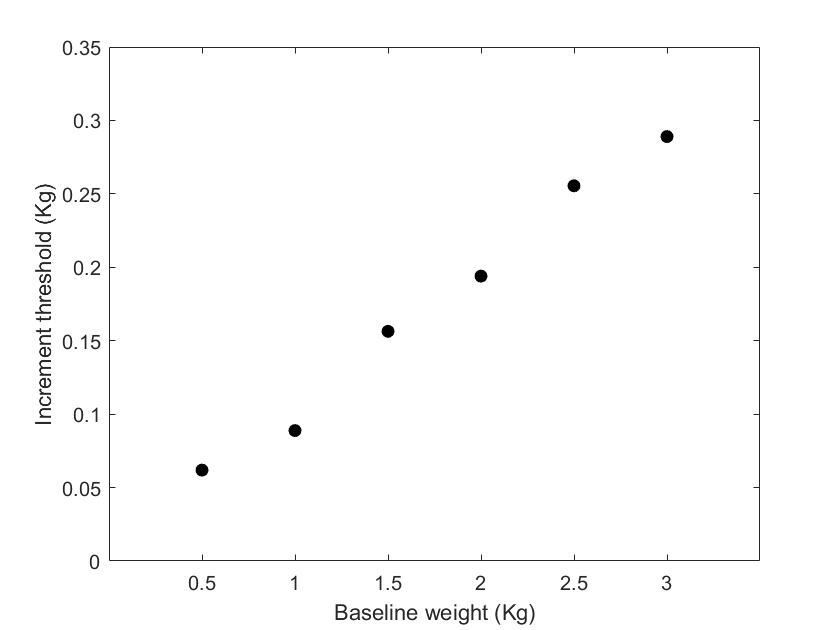

figure(1)
clf
h1=plot(x,y,'ko','MarkerFaceColor','k');
set(gca,'YLim',[0,0.35]);
set(gca,'XLim',[0,3.5]);
set(gca,'XTick',x)
xlabel('Baseline weight (Kg)');
ylabel('Increment threshold (Kg)');

## Step 1: Model Prediction

% Here's a structure containing a starting guess at the Weber fraction 'w':
startingW  =0.09;  %make this a variable to use later.
p.w = startingW;

% write a function containing the model that will predict the data & run it
% function: pred = p.w*x;
pred = WebersLaw(p,x);

% plot the prediction
disp("Plot the prediction...")

Plot the prediction...


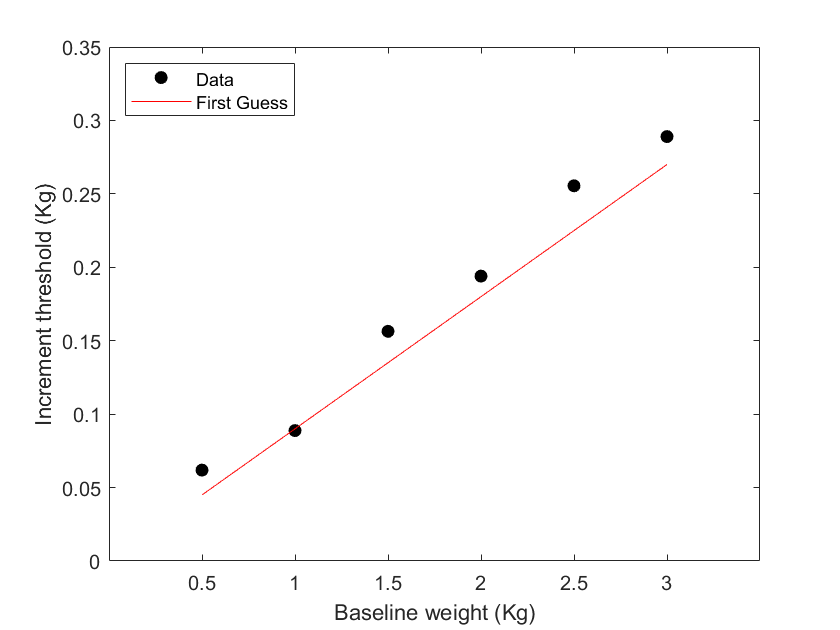

hold on
h2=plot(x,pred,'r-');
legend([h1,h2],{'Data','First Guess'},'Location','NorthWest');

## Step 2: Comparing the model prediction to the data

% Make a function that calculates the sums of squared error (SSE) between
% the model's prediction (pred) and the data (y).
% function: err = sum( (pred(:)-y(:)).^2)
disp("The SSE between our model and the data for our first guess is:")

The SSE between our model and the data for our first guess is:


err = WebersLawErr(p,x,y)

err = 0.0022


disp("But what is the best-fitting Weber fraction for our data?")

But what is the best-fitting Weber fraction for our data?


## Step 3: Finding the best fitting parameter

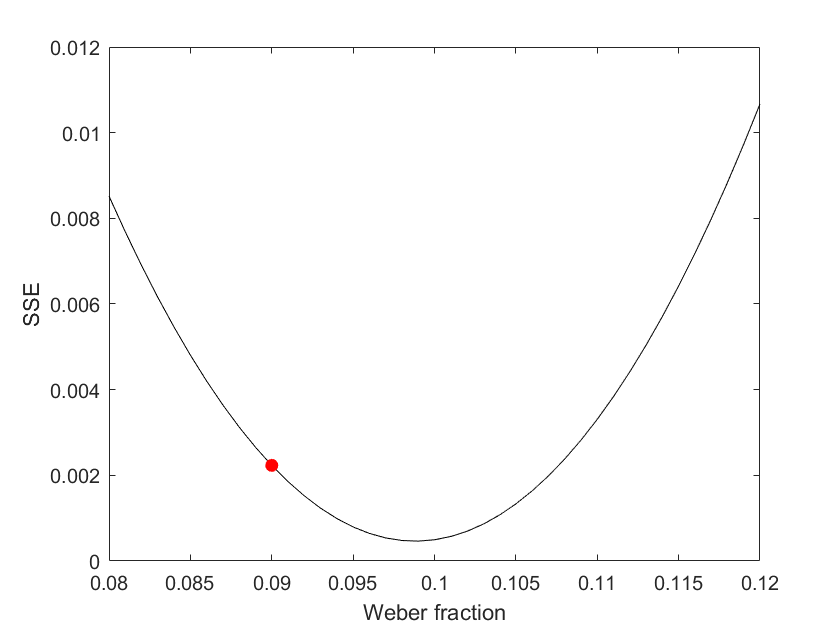

Fitting "WebersLawErr" with 1 free parameters.


Error using WebersLawErr
Too many input arguments.

Error in fminsearch (line 200)
fv(:,1) = funfcn(x,varargin{:});

Error in fit (line 41)
vars = fminsearch(funName, vars, options,params,freeList,varargin);

% What is the best fitting Weber fraction? With one parameter we can 
% visualize this problem by calculating the error of the fits for a 
% range of Weber fractions:

WeberList = linspace(0.08,0.12,41);
errList = zeros(size(WeberList));
for i=1:length(WeberList)
    p.w = WeberList(i);
    errList(i) = WebersLawErr(p,x,y);
end

figure(2)
clf
plot(WeberList,errList,'k-');
xlabel('Weber fraction');
ylabel('SSE');


% We can plot the error value of our initial guess in RED
hold on
plot(startingW,err,'ro','MarkerFaceColor','r');



[bestP,bestErr] = fit('WebersLawErr',p,{'w'},x,y);



